load("TMMcoursework2024Q1.mat");
MSOAdata.size = length(MSOAdata.code);
UTLAdata.size = length(UTLAdata.code);

a)i) Build a sparse origin-destination demand matrix and compute its row sums (total origin flows, called Oi in lectures) and column sums (total destination f lows, called Dj in lectures).

#### Including counts in the leading diagonal (for plotting now)

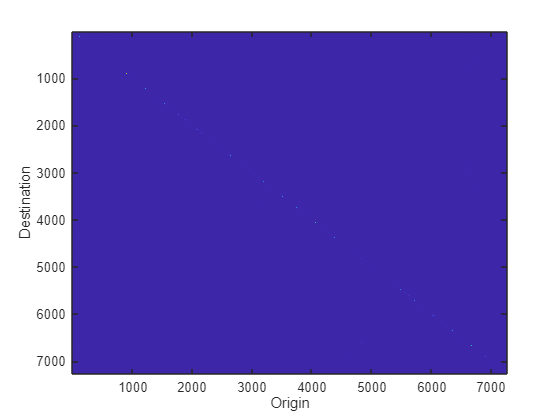

MSOAdata.odMatrixComplete = zeros(MSOAdata.size,MSOAdata.size); % initialise the OD matrix 
for x = 1:1:length(demandData.count)
    % if demandData.MSOAoriginIndex(x) ~= demandData.MSOAdestinationIndex(x) % don't include the count if it has the same O and D
    MSOAdata.odMatrixComplete(demandData.MSOAoriginIndex(x), demandData.MSOAdestinationIndex(x)) = MSOAdata.odMatrixComplete(demandData.MSOAoriginIndex(x), demandData.MSOAdestinationIndex(x)) + demandData.count(x);
    % end
end
% Convert to sparse matrix
MSOAdata.odMatrixComplete = sparse(MSOAdata.odMatrixComplete);
imagesc(MSOAdata.odMatrixComplete); % visualise the matrix
hold on;
xlabel("Origin")
ylabel("Destination")

#### excluding counts in the leading diagonals (for gravity models later)

MSOAdata.odMatrix= zeros(MSOAdata.size,MSOAdata.size); % initialise the OD matrix 
for x = 1:1:length(demandData.count)
    if demandData.MSOAoriginIndex(x) ~= demandData.MSOAdestinationIndex(x) % don't include the count if it has the same O and D
    MSOAdata.odMatrix(demandData.MSOAoriginIndex(x), demandData.MSOAdestinationIndex(x)) = MSOAdata.odMatrix(demandData.MSOAoriginIndex(x), demandData.MSOAdestinationIndex(x)) + demandData.count(x);
    end
end


% % Find the indices where origin and destination are not the same
% validIndices = demandData.MSOAoriginIndex ~= demandData.MSOAdestinationIndex;
% % Update the matrix for those valid indices
% MSOAdata.odMatrix(sub2ind(size(MSOAdata.odMatrix), demandData.MSOAoriginIndex(validIndices), ...
%     demandData.MSOAdestinationIndex(validIndices))) = demandData.count(validIndices);
% % 

MSOAdata.odMatrix = sparse(MSOAdata.odMatrix); %make sparse
%% ignore leading diagonals for Origin and Destination Flows
MSOAdata.originSums = sum(MSOAdata.odMatrix,2); %calculate 0 sum
MSOAdata.destinationSums = sum(MSOAdata.odMatrix); % calculate D sum

a)ii) Compute a matrix of the distances between the centroids of origins and destinations, being careful to state its units.

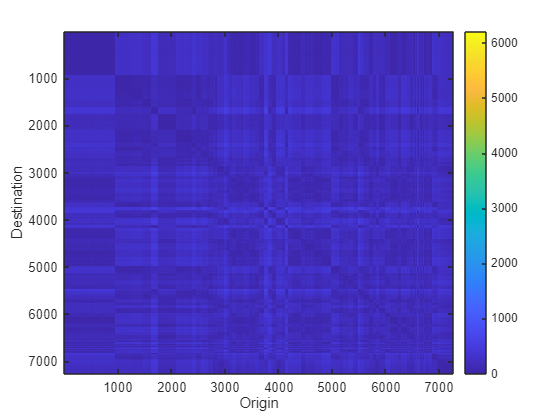

[e1, e2] = meshgrid(MSOAdata.e, MSOAdata.e);
[n1, n2] = meshgrid(MSOAdata.n, MSOAdata.n);
MSOAdata.distMat = sparse(sqrt((e2 - e1).^2 + (n2 - n1).^2)/1000); % this outputs in kilometres
imagesc(MSOAdata.distMat);

b)i) Compute the centroid of each UTLA in OS grid coordinates. (You may use a simple average of the MSOA constituent members.) Compute a matrix of distances between UTLA centroids. 

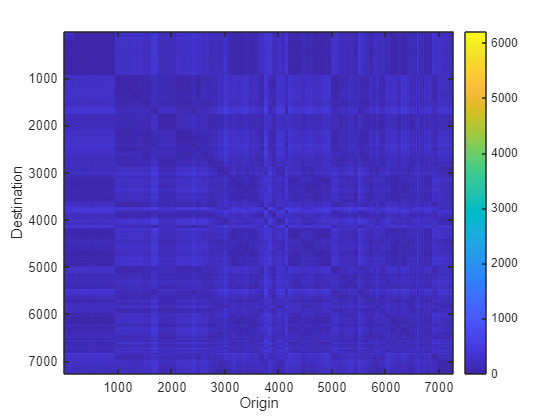

UTLAdata.n = zeros(UTLAdata.size,1);
UTLAdata.e = zeros(UTLAdata.size,1);
for x = 1:1:length(UTLAdata.code)
    % for each MSOA belonging to UTLA i, add the northing and easting and store the number of MSOA
    counter = 0;
    northing = 0;
    easting = 0;
    for y = 1:1:length(MSOAdata.UTLAindex)
        if MSOAdata.UTLAindex(y) == x
            counter = counter + 1;
            northing = northing + MSOAdata.n(y);
            easting = easting + MSOAdata.e(y);
        end
    end
    UTLAdata.n(x) = northing/counter;
    UTLAdata.e(x) = easting/counter;
end

% the index of this matrix is the origin and the destination resepctively
[e1, e2] = meshgrid(UTLAdata.e, UTLAdata.e);
[n1, n2] = meshgrid(UTLAdata.n, UTLAdata.n);
UTLAdata.distMat = sparse(sqrt((e2 - e1).^2 + (n2 - n1).^2)/1000);
imagesc(UTLAdata.distMat);

b)ii)Compute the 174 × 174 origin-destination matrix that describes flows at UTLA-UTLA level, and the corresponding row sums (origin flows) and column sums (destination flows).

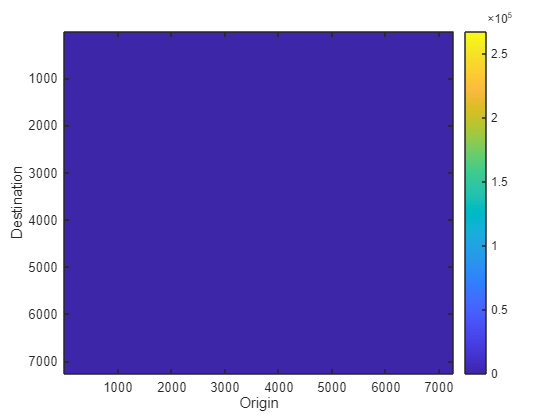

UTLAdata.odMatrix = zeros(UTLAdata.size,UTLAdata.size);
% I want to move through the entire existing MSOA OD matrix and sum/insert the value into the corresponding correct box in the UTLA OD matrix
for x = 1:1:length(MSOAdata.code)
    for y = 1:1:length(MSOAdata.code)
        UTLAdata.odMatrix(MSOAdata.UTLAindex(x), MSOAdata.UTLAindex(y)) = UTLAdata.odMatrix(MSOAdata.UTLAindex(x), MSOAdata.UTLAindex(y)) + MSOAdata.odMatrix(x,y); % plug this value into correct spot in od matrix
        % i = origin MSOA  
        % MSOAdata.UTLAindex(i) = origin UTLA
        % j = destination MSOA 
        % MSOAdata.UTLAindex(j) = destination UTLA
    end
end

UTLAdata.sparseOD = sparse(UTLAdata.odMatrix);
%% calculate O and D totals
UTLAdata.originSums = sum(UTLAdata.odMatrix,2);
UTLAdata.destinationSums = sum(UTLAdata.odMatrix);
imagesc(UTLAdata.odMatrix);